% source: https://www.kth.se/polopoly_fs/1.588039.1550155544!/Thesis%20KTH%20-%20Francesco%20Sabatino.pdf
% u = [ft; tx; ty; tz];


$$\dot{\mathbf{x}}=\mathbf{A} \cdot \mathbf{x}+\mathbf{B} \cdot \mathbf{u}+\mathbf{D} \cdot \mathbf{d}$$



$$\mathbf{x}=\left[\begin{array}{llllllllllll}
\phi & \theta & \psi & p & q & r & u & v & w & x & y & z
\end{array}\right]^{T} \in \mathbb{R}^{12}$$



$$\mathbf{u}=\left[\begin{array}{llll}
f_{t} & \tau_{x} & \tau_{y} & \tau_{z}
\end{array}\right]^{T} \in \mathbb{R}^{4}$$



$$\left[\begin{array}{lll}
\dot{\phi} & \dot{\theta} & \dot{\psi}
\end{array}\right]^{T}=\left[\begin{array}{lll}
p & q & r
\end{array}\right]^{T}$$



$$\mathbf{y}=\left[\begin{array}{llllll}
 \phi & \theta & \psi & x & y & z  
\end{array}\right]$$



$$\left\{\begin{array}{l}
\dot{\phi}=p \\
\dot{\theta}=q \\
\dot{\psi}=r \\
\dot{p}=\frac{\tau_{x}+\tau_{w x}}{I_{x}} \\
\dot{q}=\frac{\tau_{y}+\tau_{w y}}{I_{y}} \\
\dot{r}=\frac{\tau_{z}+\tau_{w z}}{I_{z}} \\
\dot{u}=-g \theta+\frac{f_{w x}}{m} \\
\dot{v}=g \phi+\frac{f_{w y}}{m} \\
\dot{w}=\frac{f_{w z}-f_{t}}{m} \\
\dot{x}=u \\
\dot{y}=v \\
\dot{z}=w
\end{array}\right.$$


clear all
close all
clc

global A;
global B;
global control;

g = 9.81;
m = 0.468;
Ix = 4.856e-3;
Iy = 4.856e-3;
Iz = 8.801e-3;

A = [0 0 0 1 0 0 0 0 0 0 0 0;
     0 0 0 0 1 0 0 0 0 0 0 0;
     0 0 0 0 0 1 0 0 0 0 0 0;
     0 0 0 0 0 0 0 0 0 0 0 0;
     0 0 0 0 0 0 0 0 0 0 0 0;
     0 0 0 0 0 0 0 0 0 0 0 0;
     0 -g 0 0 0 0 0 0 0 0 0 0;
     g 0 0 0 0 0 0 0 0 0 0 0;
     0 0 0 0 0 0 0 0 0 0 0 0;
     0 0 0 0 0 0 1 0 0 0 0 0;
     0 0 0 0 0 0 0 1 0 0 0 0;
     0 0 0 0 0 0 0 0 1 0 0 0];
 B = [0 0 0 0;
      0 0 0 0;
      0 0 0 0;
      0 1/Ix 0 0;
      0 0 1/Iy 0;
      0 0 0 1/Iz;
      0 0 0 0;
      0 0 0 0;
      1/m 0 0 0;
      0 0 0 0;
      0 0 0 0;
      0 0 0 0];
  C = [1 0 0 0 0 0 0 0 0 0 0 0;
       0 1 0 0 0 0 0 0 0 0 0 0;
       0 0 1 0 0 0 0 0 0 0 0 0;
       0 0 0 0 0 0 0 0 0 1 0 0;
       0 0 0 0 0 0 0 0 0 0 1 0;
       0 0 0 0 0 0 0 0 0 0 0 1];
  D = [0 0 0 0;
       0 0 0 0;
       0 0 0 0;
       0 0 0 0;
       0 0 0 0;
       0 0 0 0];
   
   % disturbance
  E = [0 0 0 0 0 0;
       0 0 0 0 0 0;
       0 0 0 0 0 0;
       0 0 0 1/Ix 0 0;
       0 0 0 0 1/Iy 0;
       0 0 0 0 0 1/Iz;
       1/m 0 0 0 0 0;
       0 1/m 0 0 0 0;
       0 0 1/m 0 0 0;
       0 0 0 0 0 0;
       0 0 0 0 0 0;
       0 0 0 0 0 0];

# Controller Settings

% LQR controller
Q = [1 0 0 0 0 0 0 0 0 0 0 0;
     0 1 0 0 0 0 0 0 0 0 0 0;
     0 0 1 0 0 0 0 0 0 0 0 0;
     0 0 0 .1 0 0 0 0 0 0 0 0;
     0 0 0 0 .1 0 0 0 0 0 0 0;
     0 0 0 0 0 .1 0 0 0 0 0 0;
     0 0 0 0 0 0 1 0 0 0 0 0;
     0 0 0 0 0 0 0 1 0 0 0 0;
     0 0 0 0 0 0 0 0 1 0 0 0;
     0 0 0 0 0 0 0 0 0 1 0 0;
     0 0 0 0 0 0 0 0 0 0 1 0;
     0 0 0 0 0 0 0 0 0 0 0 1];
R = 0.01 * eye(4);
K = lqr(A,B,Q,R);

x0 = zeros(12,1);  % initial condition
wr = [0; 0; 0; 0; 0; 0; 0; 0; 0; 0; 0; 1];      % reference position
u=@(x)-K*(x - wr);       % control law

# Timing Parameters

dt = 0.02;
t_total = 10;
t_attack = 5;
t_span = 0:dt:t_total;

# Simulation - No attacks

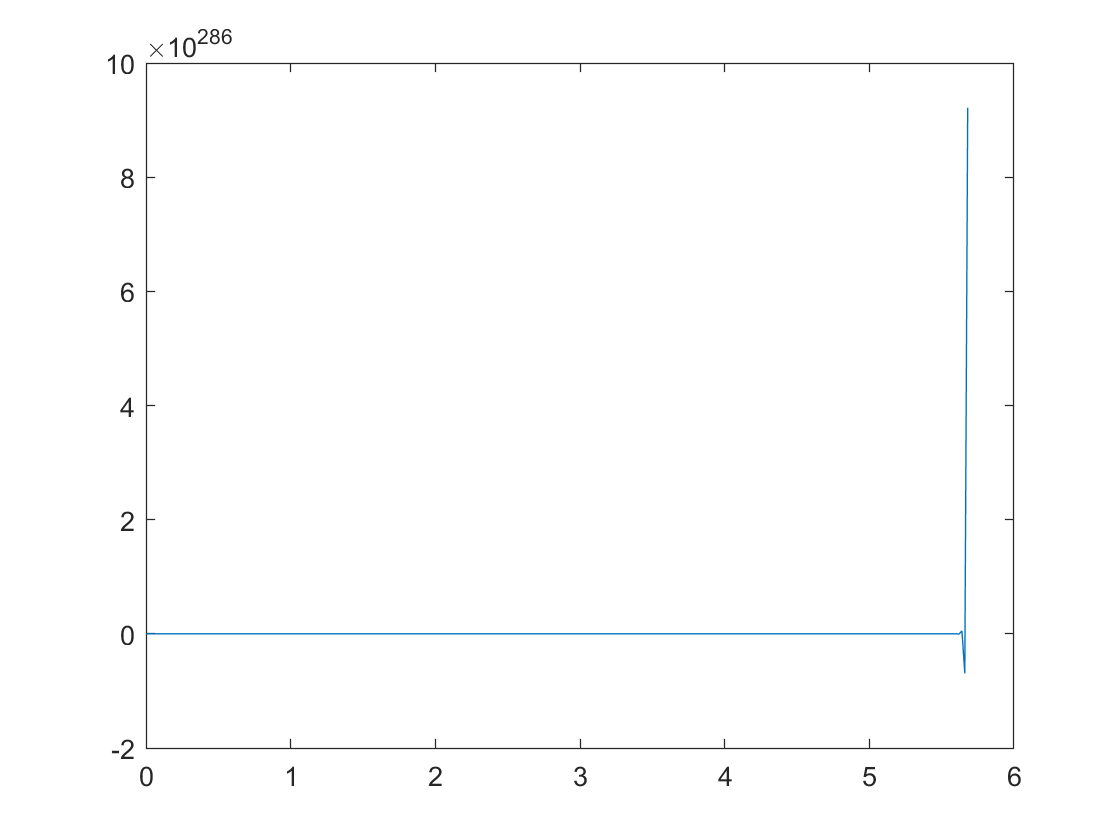

x = zeros(size(t_span,2),size(x0,1));
x(1,:) = x0';
xlast = x0;

for i = 2:(t_total/dt+1)
    control = u(xlast);
    [T, xtemp] = ode45(@dynamics, [0 dt], xlast);
    xlast = xtemp(end,:);
    x(i,:) = xlast;
    xlast = xlast';
end

plot(t_span,x(:,12))


% for k=1:10:length(t_span)
%     drawpend(x(k,:),m,M,L);
% end

function dxdt = dynamics(t, x)

global A;
global B;
global control;

dxdt = A*x + B*control;

end